 E.T.S. Ingeniería Informática                                                                               Grado en Ingeniería de la Salud

 Ampliación de Matemáticas                                                                                                           Curso 2023/24

***Práctica 4***

Considere el siguiente problema: 

		
$$u_t= c^2 u_{xx}, \qquad x \in (0,2), \qquad  t \in (0, T_f ] $$


                
$$u(x,0)=sen(\frac{(2k+1)\pi }{4} x) + k, \qquad x \in [0,2] $$


                
$$u(0,t)=k, \quad u_x(2,t)=0, \quad x \in  [0,T_f ]$$


donde k y c son constantes.

1.Determine su solución analítica.

              **Ayuda:** Busca la solución expresando $u$ como la suma $v+k$ ¿Qué problema se plantea para  $v$? ¿Cuál es su solución?

Si expresamos u(x,t) como la suma de v(x,y) + k, podemos reescribir el problema de la siguiente manera

                
$$v_t= c^2 v_{xx}, \qquad x \in (0,2), \qquad  t \in (0, T_f ] $$


                
$$v(x,0)=sen(\frac{(2k+1)\pi }{4} x), \qquad x \in [0,2] $$


                
$$v(0,t)=0, \quad v_x(2,t)=0, \quad x \in  [0,T_f ]$$


Ya que k es constante, podemos restarlo de las CC de Dirichlet y en el caso de las CC de Neumann desaparece al derivarse respecto de x. Con esto, resolvemos.

                
$$v=X(x)T(t)
\\
X(x)T(t)'= c^2 \ddot X(x)T(t)
\\
T(t)'/c^2T(t)= \ddot X(x)/X(x) = \lambda
\\
T(t)'= \lambda c^2T(t)
\\
\ddot X(x) = \lambda X(x)
\\
X(0)=0, \quad \dot X(2)=0
\\
r=\pm \sqrt \lambda
\\
\lambda > 0, X(x) = Ae^{\sqrt\lambda x}+Be^{-\sqrt\lambda x}, \dot X(x) = (\sqrt\lambda x)Ae^{\sqrt\lambda x}-(\sqrt\lambda x)Be^{-\sqrt\lambda x}
\\
X(0)=A+B=0, \dot X(2)=\sqrt\lambda 4A(e^{\sqrt\lambda 2}+e^{-\sqrt\lambda 2}) = 0
$$


No nos sirve como solución porque A y B deberían ser 0

                
$$\lambda = 0, X(x) = A+Bx, \dot X(x) = B
\\
X(0)=A=0, \dot X(2)=2B = 0$$


No sirve como solución por la misma razón que antes

                
$$\lambda < 0, X(x) = Asen(\sqrt{-\lambda} x)+Bcos(\sqrt{-\lambda} x)
\\
\dot X(x) = \sqrt{-\lambda}Acos(\sqrt{-\lambda} x)-\sqrt{-\lambda}Bsen(\sqrt{-\lambda} x)
\\
X(0)=B=0, \dot X(2)=\sqrt{-\lambda}Acos(\sqrt{-\lambda}2)
\\
\lambda=-((2n+1)/4)^2\pi^2, n\in\mathbb{N}
\\
X_n(x)=A_nsen(((2n+1)/4)\pi x)
\\
T_n(t)'=-((2n+1)/4)^2\pi^2c^2T_n(t)
\\
T_n(t)=C_ne^{-[((2n+1)/4)\pi c]^2t}
\\
v(x,t)=X(x)T(t)=D_nsen(((2n+1)/4)\pi x)e^{-[((2n+1)/4)\pi c]^2t}$$


Con las CI obtenemos

                
$$D_n=1
\\
((2n+1)/4)\pi x=((2k+1)\pi x/4)
\\
(2n+1)/4=(2k+1)/4
\\
n=k
\\
v(x,t)=sen(((2k+1)/4\pi x))e^{-[(2k+1)/4\pi c]^2t}
\\
u(x,t)=sen(((2k+1)/4\pi x))e^{-[(2k+1)/4\pi c]^2t}+k$$


2. Escriba una función en Matlab que reciba  como parámetros $k, c, Tf,  M, N$ y devuelva $x, t, u$ dos vectores y una matriz que correspondan con la solución analítica antes determinada evaluada en una partición equiespaciada en espacio y tiempo  de tamaño $M+1, N+1$, respectivamente. 

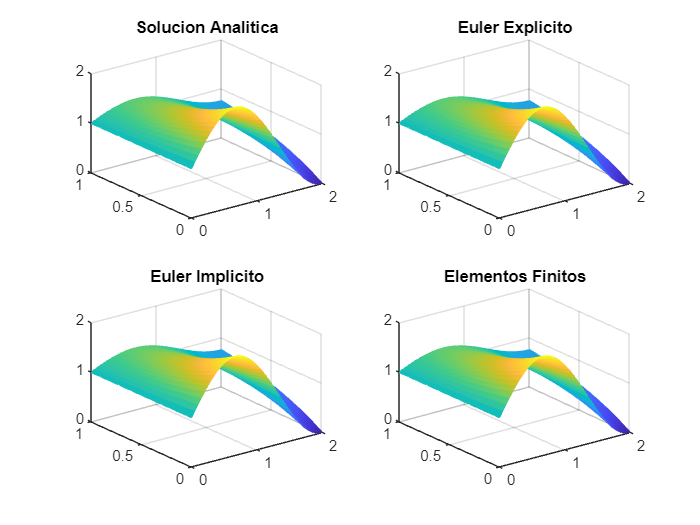

% 
figure
k=1;
c=0.5;
Tf=1;
M=40;
N=1000;
[xex,tex,yex]=SolucionAnalitica(k,c,Tf,M,N);

subplot(221)
mesh(xex,tex,yex)
title('Solucion Analitica')
subplot(222)
[xee,tee,yee]=EulerExplicito(k,c,Tf,M,N);

mesh(xee,tee,yee)
title('Euler Explicito')
subplot(223)
[xei,tei,yei]=EulerImplicito(k,c,Tf,M,N);
mesh(xei,tei,yei)
title('Euler Implicito')
subplot(224)
[xef,tef,yef]=ElementosFinitos(k,c,Tf,M,N);
mesh(xef,tef,yef)
title('Elementos Finitos')

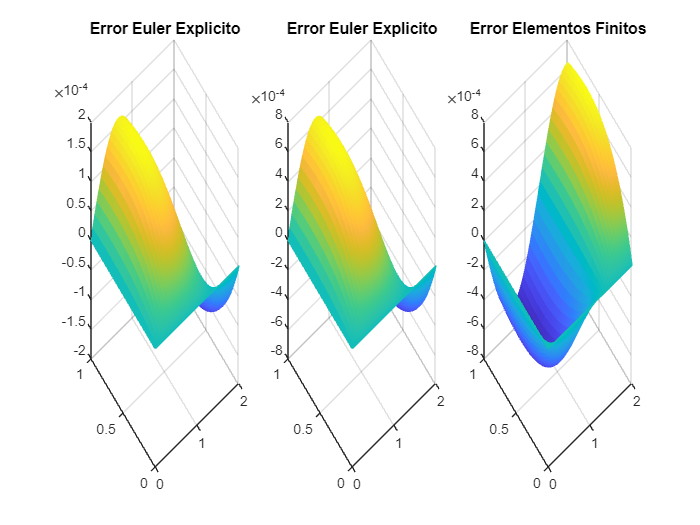


figure
subplot(131)
mesh(xee,tee,yee-yex);
title('Error Euler Explicito')
subplot(132)
mesh(xei,tei,yei-yex);
title('Error Euler Explicito')
subplot(133)
mesh(xef,tef,yef-yex);
title('Error Elementos Finitos')

function [x,t,u]=SolucionAnalitica(k,c,Tf,M,N)
% u solución del problema u_t =c u_xx x in (0,2), t in (0,Tf)
% c.i y c.c. especificadas en enunciado
% en x partición con M subintervalos del intervalo [0,2]
% y t partición con N subintervalos del intervalo [0,Tf]
ax=2./M;
at=Tf/N;
x=0:ax:2;
t=0:at:Tf;
[X,TP]=meshgrid(x,t);
u=sin((2*k+1)/4.*pi*X).*exp(-((((2*k)+1)/4*c)^2).*pi*pi*TP)+k;
end

3. Escriba funciones en Matlab que reciban los mismo parámetros que la del apartado anterior y que devuelvan las soluciones obtenidas con los métodos de Euler explícito, Euler implícito y Elementos Finitos.

Euler Explícito

                
$$x_m=m\Delta x, \qquad m=0,1,...,M, \qquad \Delta x = 2/M
\\
t_n=n\Delta t, \qquad n=0,1,...,N,  \qquad \Delta t = T/N
\\
\frac{u^{n+1}_m-u_m^n}{\Delta t}= c^2 \frac{u^{n}_{m+1}-2u_m^n+u^n_{m-1}}{\Delta x^2}
$$


                
$$
u^0_m=sen(\frac{(2k+1)\pi }{4} x_m)+k, \qquad m=1,...,M-1
\\
u^n_0=k, \qquad n=0,1,...,N
\\
\frac{u^n_{M+1}-u^n_{M-1}}{2\Delta x}=u^n_M=0, \quad u^n_{M+1}=u^n_{M-1}, \quad n=0,1,...,N
\\
$$


                
$$U^{n+1}=AU^n+B^n$$


Euler Implícito

                
$$x_m=m\Delta x, \qquad m=0,1,...,M, \qquad \Delta x = 2/M
\\
t_n=n\Delta t, \qquad n=0,1,...,N,  \qquad \Delta t = T/N
\\
\frac{u^{n+1}_m-u_m^n}{\Delta t}= c^2 \frac{u^{n+1}_{m+1}-2u_m^{n+1}+u^{n+1}_{m-1}}{\Delta x^2}
$$


                
$$
u^0_m=sen(\frac{(2k+1)\pi }{4} x_m)+k, \qquad m=1,...,M-1
\\
u^n_0=k, \qquad n=0,1,...,N
\\
\frac{u^n_{M+1}-u^n_{M-1}}{2\Delta x}=u^n_M=0, \quad u^n_{M+1}=u^n_{M-1}, \quad n=0,1,...,N
\\
$$


                
$$AU^{n+1}=(U^n+B^n)$$


function [x,t,y]=EulerExplicito(k,c,Tf,M,N)
% u solución aproximada del problema u_t =c u_xx x in (0,2), t in (0,Tf)
% c.i y c.c. especificadas en enunciado
% en x partición con M subintervalos del intervalo [0,2]
% y t partición con N subintervalos del intervalo [0,Tf]
% obtenida con el método de Euler Explícito
ax=2./M;
at=Tf/N;
r=at/ax^2;
x=0:ax:2;
t=0:at:Tf;
m=length(x);
n=length(t);
A=(1.-2*c^2*r)*eye(m-1)+r*c^2*diag(ones(m-2,1),1)+r*c^2*diag(ones(m-2,1),-1);
%length(A)
A(M,M-1)=2*A(M,M-1);
B=zeros(1,M);
B(1,1)=k*c^2*r;
y=zeros(n,m);
%length(y)
y(:,1)=k;
y(1,:)=sin(((2*k+1)/4).*pi.*x)+k;
for j=1:N
    y(j+1,2:m)=(A*y(j,2:m)'+B')';
end
end

function [x,t,y]=EulerImplicito(k,c,Tf,M,N)
% u solución aproximada del problema u_t =c u_xx x in (0,2), t in (0,Tf)
% c.i y c.c. especificadas en enunciado
% en x partición con M subintervalos del intervalo [0,2]
% y t partición con N subintervalos del intervalo [0,Tf]
% obtenida con el método de Euler Implícito
ax=2./M;
at=Tf/N;
r=at/ax^2;
x=0:ax:2;
t=0:at:Tf;
m=length(x);
n=length(t);
A=(1.+2*c^2*r)*eye(m-1)-r*c^2*diag(ones(m-2,1),1)-r*c^2*diag(ones(m-2,1),-1);
A(M,M-1)=2*A(M,M-1);
B=zeros(1,M);
B(1,1)=c^2*r*k;
y=zeros(n,m);
y(:,1)=k;
y(1,:)=sin(((2*k+1)/4).*pi.*x)+k;

for j=1:N
    y(j+1,2:m)=A\(y(j,2:m)'+B');
end
end

function [x,t,y]=ElementosFinitos(k,c,Tf,M,N)
% u solución aproximada del problema u_t =c u_xx x in (0,2), t in (0,Tf)
% c.i y c.c. especificadas en enunciado
% en x partición con M subintervalos del intervalo [0,2]
% y t partición con N subintervalos del intervalo [0,Tf]
% obtenida con un método de elementos finitos
ax=2./M;
at=Tf/N;
x=0:ax:2;
t=0:at:Tf;
m=length(x);
n=length(t);
c1=2./ax;
c2=-1./ax;
a1=2.*ax/3.;
a2=ax/6.;
A=a1*eye(m-1)+a2*diag(ones(m-2,1),1)+a2*diag(ones(m-2,1),-1);
A(m-1,m-1)=A(m-1,m-1)/2;
B=-c^2*(c1*eye(m-1)+c2*diag(ones(m-2,1),1)+c2*diag(ones(m-2,1),-1));
B(m-1,m-1)=B(m-1,m-1)/2;
C=zeros(m-1,1);
C(1,1)=-c^2*k*c2;

D=A\B;

Mt=A\C;
% resolvemos U'=(A\B)U+A\C con Euler explicito

y=k*ones(n,m);
num=((2*k+1)/4*pi);
y(1,:)=sin(num.*x)+k;

for k=1:N
    y(k+1,2:m)=((eye(m-1)+D*at)*y(k,2:m)'+at*Mt)';
end


end

4. Utilice estas funciones para resolver los problemas propuestos con distintos valores de k, c, $Tf$, $M$ y $N$. 

5. Compare la solución analítica con las obtenidas utilizando los métodos numéricos y comente los resultados.

Algunas cuestiones que puede comentar:

- ¿Qué valores de k y c ha utilizado? ¿Importa su signo o que valga 0? 

-  Considere el caso k=2, c=5. ¿Cómo elige $Tf$? ¿Hay algún valor de $Tf$ que le parezca más interesante?

- ¿Dependen los resultados de los valores de $M$ y $N$ elegidos? ¿Tiene que seleccionarlos teniendo en cuenta alguna restricción?

-  ¿Observa en sus resultados la consistencia y estabilidad de los métodos de diferencias finitas utilizados?

- ¿Cómo ha implementado el método de elementos finitos? ¿Ha tenido que tomar alguna decisión? Si es así, ¿cómo justifica su elección?

Sería interesante implemetar también los otros métodos de diferencias finitas visto en clase (Crank-Nicholson, Richardson, DuFort-Frankel) y observar su comportamiento.